# **Matlab Code and Results**

Importing the audio file and assigning the parameters

[audio_in,sample_frequency]=audioread('mixed.wav');
mm=[];
frequency_list=[];
sample_time=1/sample_frequency;
t=(1:6000)*sample_time;
N=length(t);

Assigning Note Lookup Table

note_names=['C0','G1','G2','D3','G3','B3','D4','F4','G4','A4','B4','B5','B8'];
note_frequency=[50 103 150 200 250 300 350 400 441 500 1000 1500 10003];

Fourier transform algorithm implementation

for(k=1:N)
    for(n=1:N)
        y1(n)=audio_in(n).*exp(-1i*2*pi*((-N/2)+n-1)*((-N/2)+k-1)/N);
    end
    mm=[mm sum(y1)];
end

Plotting the fourier spectrum of audio file

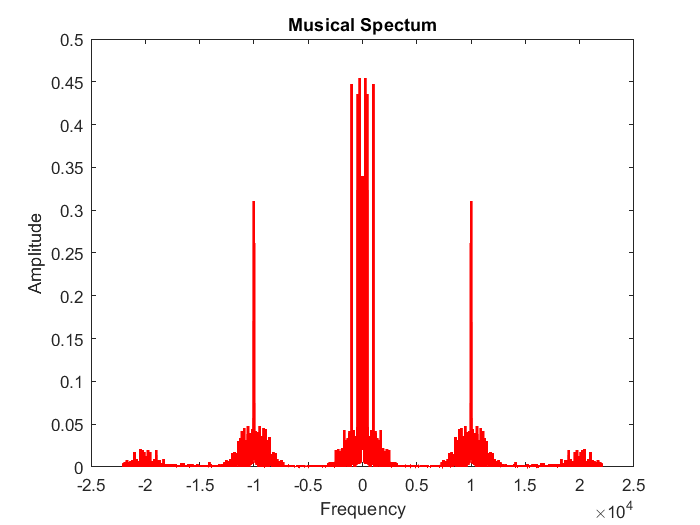

 
f=sample_frequency.*(-N/2:N/2-1)/N;
figure
grid on
y=2*abs(mm)/N;
plot(f,y,'r','lineWidth',2);
title('Musical Spectum')
xlabel('Frequency')
ylabel('Amplitude')

Find the dominant frequnecy and maximum amplitude of 1st tone

 
amplitude_array=2*abs(mm)/N;
maximum_amplitude=max(amplitude_array);
txt0=['1st Maximum Amplitude is : ',num2str(maximum_amplitude)];
disp(txt0)

1st Maximum Amplitude is : 0.45391


dominant_frequency=round(f(y==max(amplitude_array)));
txt1=['1st Dominant Frequency is : ',num2str(dominant_frequency(1,2)),' Hz'];
disp(txt1)

1st Dominant Frequency is : 250 Hz


frequency_list=[frequency_list dominant_frequency(1,2)];

Identification of Note 1

pos=find(note_frequency==dominant_frequency(1,2));
numm=note_names(pos*2);
alphabett=note_names(pos*2-1);
name=['Note Name = ',alphabett,numm];
disp(name)

Note Name = G3


Identifying the dominant frequency and maximum amplitude of 2nd tone

 
amplitude_array_sorted = unique(amplitude_array);
maximum_amplitude2 = amplitude_array_sorted(1,end-1);
txt2=['2nd Maximum Amplitude is : ',num2str(maximum_amplitude2)];
disp(txt2)

2nd Maximum Amplitude is : 0.44689


dominant_frequency2=round(f(y==maximum_amplitude2));
txt3=['2nd Dominant Frequency is : ',num2str(dominant_frequency2(1,2)),' Hz'];
disp(txt3)

2nd Dominant Frequency is : 1000 Hz


frequency_list=[frequency_list dominant_frequency2(1,2)];

Identification of Note 2

pos=find(note_frequency==dominant_frequency2(1,2));
numm=note_names(pos*2);
alphabett=note_names(pos*2-1);
name=['Note Name = ',alphabett,numm];
disp(name)

Note Name = B4


Identifying the dominant frequency and maximum amplitude of 3rd tone

 
amplitude_array_sorted = unique(amplitude_array);
maximum_amplitude3 = amplitude_array_sorted(1,end-2);
txt4=['3rd Maximum Amplitude is : ',num2str(maximum_amplitude3)];
disp(txt4)

3rd Maximum Amplitude is : 0.43596


dominant_frequency3=round(f(y==maximum_amplitude3));
txt5=['3rd Dominant Frequency is : ',num2str(dominant_frequency3(1,2)),' Hz'];
disp(txt5)

3rd Dominant Frequency is : 441 Hz


frequency_list=[frequency_list dominant_frequency3(1,2)];

Identification of Note 3

pos=find(note_frequency==dominant_frequency3(1,2));
numm=note_names(pos*2);
alphabett=note_names(pos*2-1);
name=['Note Name = ',alphabett,numm];
disp(name)

Note Name = G4


Identifying the dominant frequency and maximum amplitude of 4th tone

 
amplitude_array_sorted = unique(amplitude_array);
maximum_amplitude4 = amplitude_array_sorted(1,end-3);
txt6=['4th Maximum Amplitude is : ',num2str(maximum_amplitude4)];
disp(txt6)

4th Maximum Amplitude is : 0.33919


dominant_frequency4=round(f(y==maximum_amplitude4));
txt7=['4th Dominant Frequency is : ',num2str(dominant_frequency4(1,2)),' Hz'];
disp(txt7)

4th Dominant Frequency is : 103 Hz


frequency_list=[frequency_list dominant_frequency4(1,2)];

Identification of Note 4

pos=find(note_frequency==dominant_frequency4(1,2));
numm=note_names(pos*2);
alphabett=note_names(pos*2-1);
name=['Note Name = ',alphabett,numm];
disp(name)

Note Name = G1


Identifying the dominant frequency and maximum amplitude of 5th tone

 
amplitude_array_sorted = unique(amplitude_array);
maximum_amplitude5 = amplitude_array_sorted(1,end-4);
txt8=['5th Maximum Amplitude is : ',num2str(maximum_amplitude5)];
disp(txt8)

5th Maximum Amplitude is : 0.31104


dominant_frequency5=round(f(y==maximum_amplitude5));
txt9=['5th Dominant Frequency is : ',num2str(dominant_frequency5(1,2)),' Hz'];
disp(txt9)

5th Dominant Frequency is : 10003 Hz


frequency_list=[frequency_list dominant_frequency5(1,2)];

Identification of Note 5

pos=find(note_frequency==dominant_frequency5(1,2));
numm=note_names(pos*2);
alphabett=note_names(pos*2-1);
name=['Note Name = ',alphabett,numm];
disp(name)

Note Name = B8
